# Kinematyka robota mobilnego

clear all; clc; close all;

## Parametry symulacji

dt=0.1; % krok całkowania
ts=15; % czas symulacji
t=0:dt:ts; %time span



## Warunki początkowe

x0=0.5;
y0=0.5;

psi0=0;

eta0=[x0;y0;psi0];

eta(: , 1) = eta0; % przypisanie pierwszej kolumnie 
                   % trzech warunków początkowych w kolejnych wierszach

## Start pętli

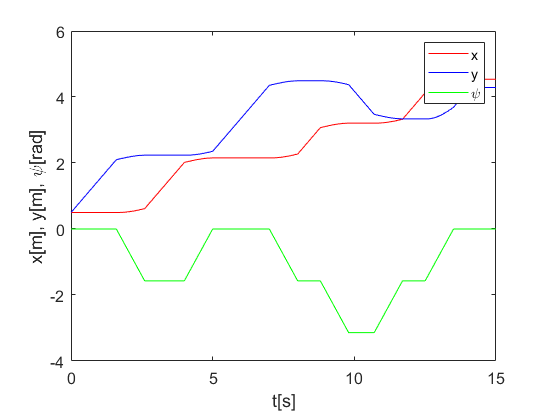

for i=1:length(t)
    time = i*dt;

    psi = eta(3,i); %aktualna orientacja w rad
    %Jakobian macierzy:
    J_psi=[cos(psi),-sin(psi),0;
           sin(psi),cos(psi),0;
           0,0,1];

    % Warunki dla poruszania się

    if(time <= 1.6) %do góry
        u = 0; 
        v = 1; 
        r = 0;
        
    elseif(time > 1.6) && (time <= 2.6) %zakręt w prawo
        u = 0; 
        v = 0.2; 
        r = -pi/2;
    elseif(time > 2.6) && (time <= 4) %do przodu
        u = 0; 
        v = 1; 
        r = 0;   
    elseif(time > 4) && (time <= 5) %zakręt w lewo
        u = 0; 
        v = 0.2; 
        r = pi/2;  
    elseif(time > 5) && (time <= 7) %do przodu
        u = 0; 
        v = 1; 
        r = 0; 
    elseif(time > 7) && (time <= 8) %zakręt w prawo
        u = 0; 
        v = 0.2; 
        r = -pi/2; 
    elseif(time > 8) && (time <= 8.8) %do przodu
        u = 0; 
        v = 1; 
        r = 0;
    elseif(time > 8.8) && (time <= 9.8) %zakręt w prawo
        u = 0; 
        v = 0.2; 
        r = -pi/2; 
    elseif(time > 9.8) && (time <= 10.75) %do przodu
        u = 0; 
        v = 1; 
        r = 0;
    elseif(time > 10.75) && (time <= 11.75) %zakręt w lewo
        u = 0; 
        v = 0.2; 
        r = pi/2;
    elseif(time > 11.75) && (time <= 12.5) %do przodu
        u = 0; 
        v = 1; 
        r = 0;
    elseif(time > 12.5) && (time <= 13.5) %zakręt w lewo
        u = 0; 
        v = 0.6; 
        r = pi/2;
    
    elseif(time > 13.5) && (time <= 14.2) %do przodu
        u = 0; 
        v = 1; 
        r = 0;    
    elseif(time > 14.2) && (time <= 15)
        u = 0; 
        v = 0; 
        r = 0; 
    end

       
       zeta(:,i)=[u;v;r];
       
       eta_dot(:,i) = J_psi*zeta(:,i);
       
       eta(:,i+1) = eta(:,i)+dt*eta_dot(:,i); % metoda Eulera
end

% %% Wydruk funkcji
 
 figure
 plot(t, eta(1,1:i),'r-');
 hold on
 
 plot(t, eta(2,1:i),'b-');
 hold on
 
 plot(t, eta(3,1:i),'g-');
 
 xlabel('t[s]');
 ylabel('x[m], y[m], \psi[rad]');
 legend('x','y','\psi'), set(gca,'fontsize',12);

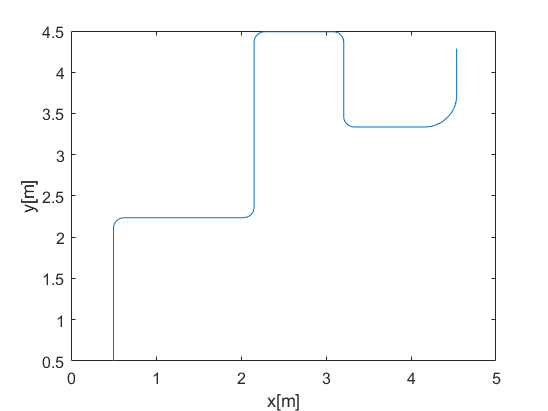

 
 figure
 plot(eta(1,1:i), eta(2,1:i));
xlabel('x[m]');
ylabel('y[m]');
set(gca,'fontsize',12);

## Animacja ruchu robota mobilnego

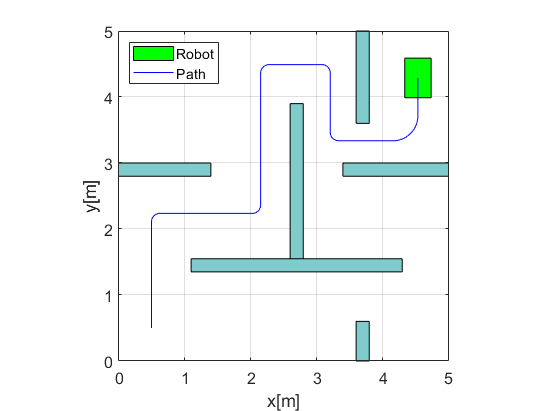

%% Animacja ruchu robota mobilnego z przeszkodami
l=0.4; % długość platformy
w=0.6; % szerokość platformy

% Współrzędne opisujące kształt platformy robota
mr_co=[-l/2,l/2,l/2,-l/2,-l/2;
        -w/2,-w/2,w/2,w/2,-w/2];

% Współrzędne ścian
walls = [
    0, 2.8, 1.4, 0.2;  
    3.6, 0, 0.2, 0.6;
    3.4, 2.8, 1.6, 0.2;
    3.6, 3.6, 0.2, 1.4;
    1.1, 1.35,  3.2, 0.2;
    2.6, 1.55,  0.2, 2.35;
];

figure
for i=1:length(t) % początek animacji

    psi = eta(3,i);
    R_psi = [cos(psi), -sin(psi);
             sin(psi), cos(psi)]; % macierz rotacji
    v_pos = R_psi * mr_co;

    % Rysowanie robota
    fill(v_pos(1,:)+eta(1,i), v_pos(2,:)+eta(2,i),'g'); % robot
    hold on, grid on;
    
    %ściany
    for j = 1:size(walls, 1)
        % Każda ściana
        rectangle('Position', [walls(j,1), walls(j,2), walls(j,3), walls(j,4)], ...
                  'FaceColor', [0.5, 0.8, 0.8], 'EdgeColor', 'k', 'LineWidth', 0.5);
    end

    axis([0 5 0 5]), axis square
    plot(eta(1,1:i), eta(2,1:i), 'b-'); % ścieżka ruchu

    legend('Robot','Path','Location','northwest'), set(gca,'fontsize',12)
    xlabel('x[m]'); ylabel('y[m]');
    pause(0.1);
    hold off
end % koniec animacji